## Problem 2

### Part (A)

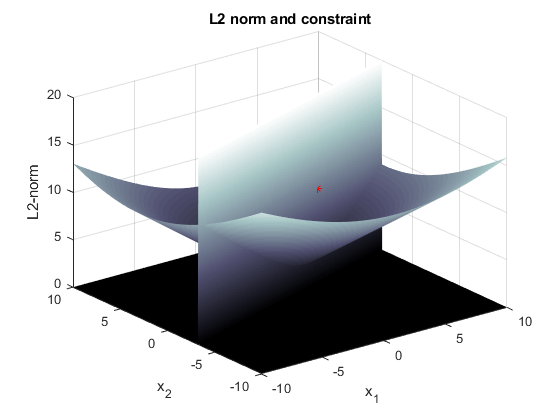

%% Setup
A = [1,0;0,1];
b = [3;1];
C = [3,-1];
d = 0;
x = (-10:.05:10)';
[xx,yy] = meshgrid(x,x); %treat as discretized x1,x2 variables

%% Plot L2 norm and constraint over span of x1,x2 variables
L2norm = zeros(size(xx));
Const = zeros(size(xx));
for i = 1:length(xx)
    for j = 1:length(yy)
        z = [yy(i,j);xx(i,j)];
        xhat = A*z-b;
        L2norm(i,j) = rssq(xhat,1);
        Const(i,j) = abs(C*z-d)<0.15; %boolean
        Const = double(Const); %double
    end 
end 
figure; surf(xx,yy,L2norm); hold on
surf(xx,yy,Const*20); plot3(b(1),b(2),10,'r*');
shading interp; title('L2 norm and constraint'); xlabel('x_1'); ylabel('x_2'); zlabel('L2-norm')
colormap bone; hold off

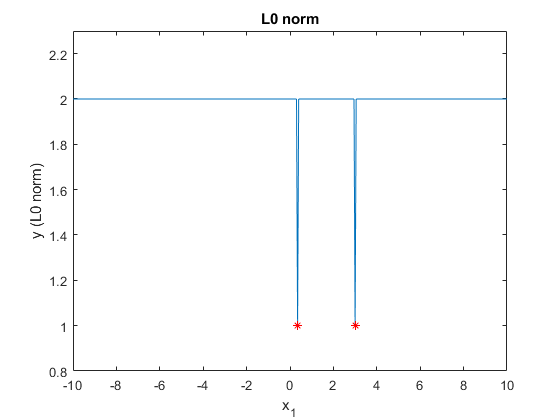


%% Constrain solutions to 1D
y = 3*x; %1D solution to linear equation
X = [x,y]';

%% Find the L0 norm
X0 = X-b;
X0(X0~=0)=1; %turn nonzero values into 1's
X0(2,208)=0;
L0 = abs(sum(X0,1));
[min0,ind0] = min(L0); %NOT THE ONLY MIN
figure; plot(x,L0); hold on; 
plot(3,1,'r*'); plot(0.333,1,'r*'); hold off
xlim([-10,10]); ylim([0.8,2.3]); 
title('L0 norm'); xlabel('x_1'); ylabel('y (L0 norm)');

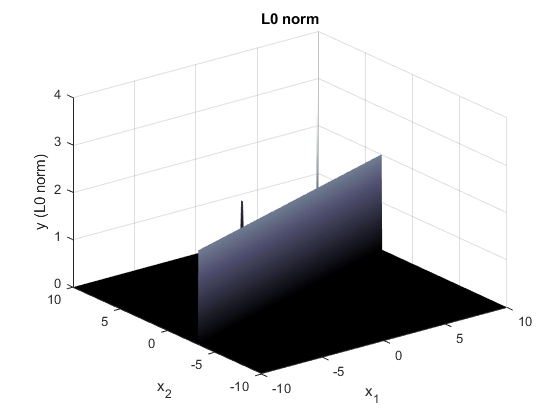


L0x = xx; L0y = yy;
L0x(abs(L0x-3)>0)=1; L0y(abs(L0y-1)>0)=1;
L0full = (L0x+L0y).*Const;
L0full(379:383,261) = 1;
L0full(220:221,207:208) = 1;
figure; surf(xx,yy,L0full); shading interp;
title('L0 norm'); xlabel('x_1'); ylabel('x_2'); zlabel('y (L0 norm)')
colormap bone; 

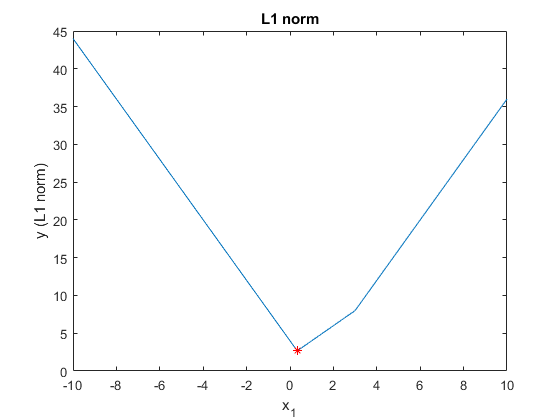


%% Find the L1 norm
X1 = A*X-b;
L1 = sum(abs(X1),1);
[min1,ind1] = min(L1);
figure; plot(x,L1); hold on;
plot(x(208),2.7,'r*'); hold off
title('L1 norm'); xlabel('x_1'); ylabel('y (L1 norm)');

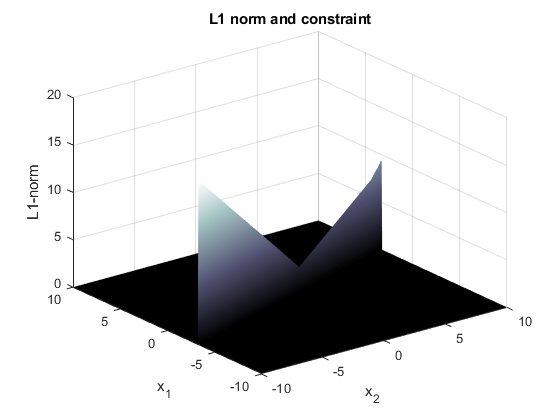


for i = 1:length(xx)
    for j = 1:length(yy)
        z = [yy(i,j);xx(i,j)];
        Const(i,j) = abs(C*z-d)<0.15; %boolean
        Const = double(Const); %double
        xhat = (A*z-b);
        L1full(i,j) = sum(abs(xhat),1).*Const(i,j);
    end 
end 
figure; surf(xx,yy,L1full);
shading interp; title('L1 norm and constraint'); xlabel('x_2'); ylabel('x_1'); zlabel('L1-norm')
colormap bone; hold off

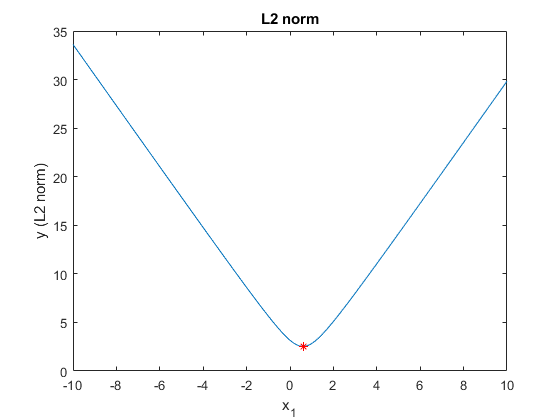


%% Find the L2 norm
X2 = A*X-b;
L2 = rssq(X2,1);
[min2,ind2] = min(L2);
figure; plot(x,L2); hold on
plot(x(213),L2(213),'r*'); hold off
title('L2 norm'); xlabel('x_1'); ylabel('y (L2 norm)');

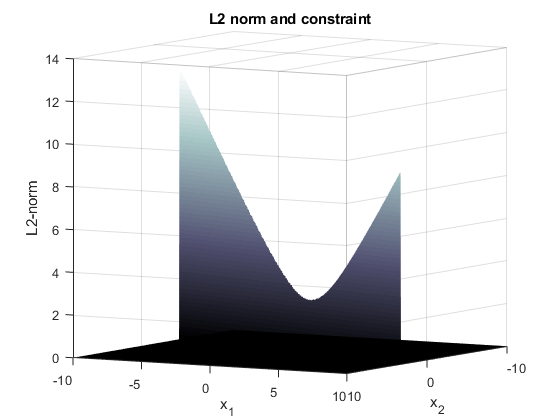


L2full = L2norm.*Const;
figure; surf(xx,yy,L2full);
shading interp; title('L2 norm and constraint'); xlabel('x_1'); ylabel('x_2'); zlabel('L2-norm')
colormap bone;

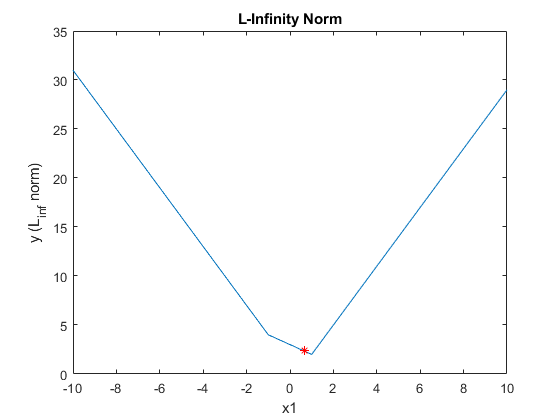


%% Find the L-infinity norm
X8 = A*X-b;
L8 = max(abs(X8),[],1);
[min8,ind8] = min(L8);
figure; plot(x,L8); hold on
plot(x(ind8),L8(ind8),'r*'); hold off
title('L-Infinity Norm');xlabel('x1'); ylabel('y (L_{inf} norm)')

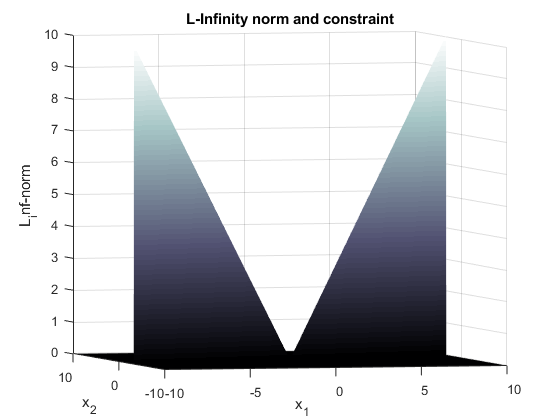

for i = 1:length(xx)
    for j = 1:length(yy)
        z = [yy(i,j);xx(i,j)];
        xhat = (A*z-b);
        L8max(i,j) = max(abs(xhat));
    end 
end 
L8full = L8max.*Const;
figure; surf(xx,yy,L8full);
shading interp; title('L-Infinity norm and constraint'); xlabel('x_2'); ylabel('x_1'); zlabel('L_inf-norm')
colormap bone;